# Explore the dynamics of a TRIPLE compound **Pendulum**

In this example we're going to define the model parameters for our triple compound pendulum.  The system that we're going to explore is shown below:

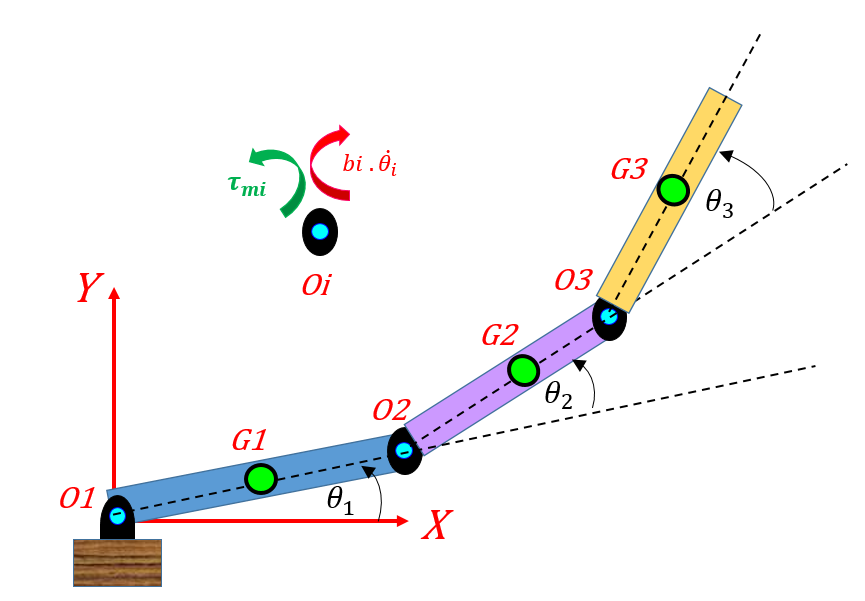

`Bradley Horton : 01-Aug-2016, bradley.horton@mathworks.com.au`

## Define some model parameters for LINK 1 and LINK 2 and LINK 3:

We'll represent each link in the pendulum as a rectangular prism(or BRICK).  So one of the first things we'll need are the inertia properties of the 3 links. We'll assume that each link has the same density.

density = 1000; % kg/m3

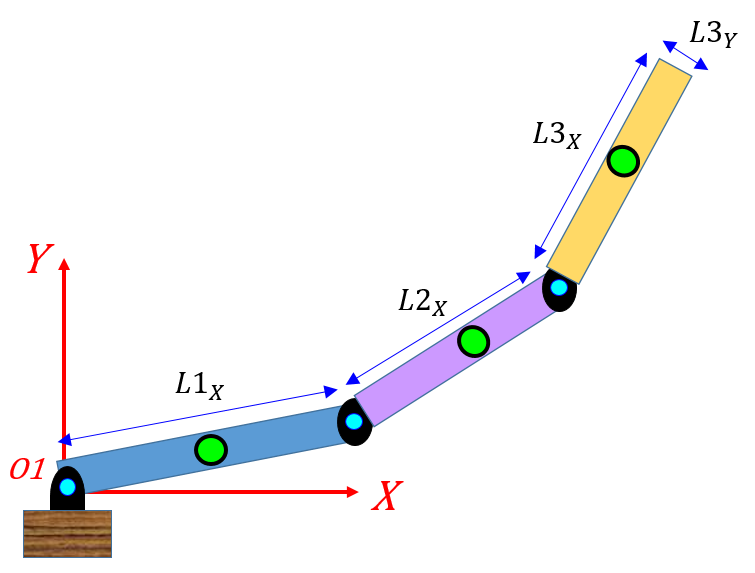

## Define some geometry parameters for LINK 1:

L1x     = 0.75; % m
L1y     = 0.050; % m
L1z     = 0.005; % m
mass1   = density * L1x*L1y*L1z; % kg

Calculate the inertia relative to the center of mass (eg: see [**HERE**](https://en.wikipedia.org/wiki/List_of_moments_of_inertia))

I1g      = mass1*(L1x^2 + L1y^2)/12;

## Define some geometry parameters for LINK 2:

L2x     = 0.50; % m
L2y     = 0.05; % m
L2z     = 0.005; % m
mass2   = density * L2x*L2y*L2z; % kg

Calculate the inertia relative to the center of mass (eg: see [**HERE**](https://en.wikipedia.org/wiki/List_of_moments_of_inertia))

I2g      = mass2*(L2x^2 + L2y^2)/12;

## Define some geometry parameters for LINK 3:

L3x     = 0.25; % m
L3y     = 0.05; % m
L3z     = 0.005; % m
mass3   = density * L3x*L3y*L3z; % kg

Calculate the inertia relative to the center of mass (eg: see [**HERE**](https://en.wikipedia.org/wiki/List_of_moments_of_inertia))

I3g      = mass3*(L3x^2 + L3y^2)/12;

Calculate the inertia relative to the pivot point "O2" using the parallel axis theorem:

I3o      = I3g + mass3*(L3x/2)^2;

## Define some damping at each joint:

We will assume that each pivot point experiences viscous damping, ie: $\tau_{damping} = b \thinspace \dot{\theta}$.   Note that the damping torque is a function of the relative joint velocity, eg: $\tau_2 = b_2 \thinspace . \thinspace \dot{\theta}_2$.

b1_damp = 0.005; %0.1 (N.m/(rad/sec));
b2_damp = 0.005; %0.1 (N.m/(rad/sec));
b3_damp = 0.005; %0.1 (N.m/(rad/sec));

## Define gravity:

We'll assume that gravity acts in the negative Y-direction.

g = 9.80665;  % m/sec^2

## The System pose and INITIAL Conditions:

Here is how we'll describe the angular displacement of the 2 links.

 

Here are the system INITIAL conditions - note all units are either (rad) or (rad/sec)

- $\theta_1(0) = 0
$,       `      (rad)`

- $\dot{\theta}_1(0) = 0$         `      (rad/sec)`

- $\theta_2(0) = 0$    `        (rad)`

- $\dot{\theta}_2(0) = 0$         `      (rad/sec)`

- $\theta_3(0) = 0$    `        (rad)`

- $\dot{\theta}_3(0) = 0$         `      (rad/sec)`

theta1_0     =  0;                    % rad
theta1_dot_0 =  0;                    % rad/sec 
theta2_0     =  0;                    % rad
theta2_dot_0 =  0;                    % rad/sec
theta3_0     =  0;                    % rad
theta3_dot_0 =  0;                    % rad/sec